# CCNY Ozone-DIAL retrievals

Orignially written by Dr.Li in 2022-2023-2024

Wu add: aerosol correction for the O3 retrievals at near-range channel Aug.28, 2024

clearvars; close all;

addpath(genpath('./functions'));

% input_data_path = strcat('C:\Users\Thomas\OneDrive - The City College of New York\Desktop\input_data\','\');
% input_data_path = strcat('C:\Users\Thomas Ely\OneDrive - The City College of New York\Desktop\input_data','\');
input_data_path = strcat('C:\Users\tely1\OneDrive - The City College of New York\Desktop\input_data','\');


if ~exist(input_data_path, "dir")
    mkdir(input_data_path)
end

Automatic downloading of data is sometimes buggy

download_data = true;

## Load lidar data files, get time average, dead-time correction, and background-noise subtraction 

Select date to process lidar data. If data on that date is available on the server, it will be downloaded and processed.

Recent data has 8000 bins but older data may have 6000 or 4000 bins.

Resulting profile data are saved in results folder inside this repository

file_date_dt = datetime("2022-07-20", "InputFormat", "uuuu-MM-dd"); file_date = string(datetime(file_date_dt, "Format","uuuuMMdd"));
folder_path = strcat(input_data_path, file_date, '/txt/');
save_path = strcat('./results/', file_date,'/');
[st,f] = mkdir(save_path);

nbin = 8000;
dzm = 3.75;
bgbins = 100;
td = 280;
nAvg = 10;
sib_hkm = 12; % the begining range for sib correction fitting curve

if download_data == true
    download_lidar_data(file_date_dt, input_data_path)
end

Error downloading lidar data



% for the first time run, load the original txt files into mat file

TODO: add a check if this .mat file exists already, and skip reading if it does

OLfileName = read_OL_profiles(folder_path, save_path, nbin, dzm, bgbins, td, nAvg, sib_hkm);
load(OLfileName);

ids = size(sigprof.an287fr, 2);

Remove signals from before gate is activated

% Far-ch and near-ch PMT gate start time
% start_bin_fr = 190; % 190-bin = 4.75 us, 712.5 m, normally
start_bin_fr = 135; % 135-bin = 3.375 us, 506.25 m on Nov.15
start_bin_nr = 20;

[gated_sigprof, hkm_fr, hkm_nr] = gate_prof(sigprof, start_bin_fr, start_bin_nr, hkm);

nr_id = start_bin_nr:nbin;
fr_id = start_bin_fr:nbin;

diff_nr_fr = size(hkm_nr,1) - size(hkm_fr,1);

## Raw Signal Profiles Plot

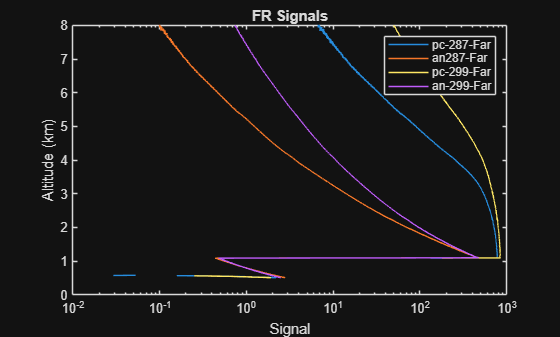

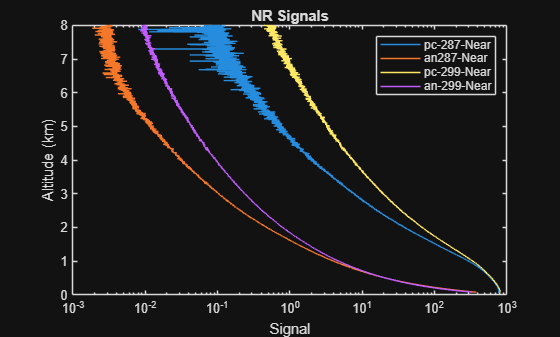

Show = true;
if Show == true
    id = 1;
    signal_plot('FR Signals',{'pc-287-Far','an287-Far','pc-299-Far','an-299-Far'},id,sigprof.pc287fr(fr_id,:),sigprof.an287fr(fr_id,:),sigprof.pc299fr(fr_id,:),sigprof.an299fr(fr_id,:), hkm(fr_id))
    signal_plot('NR Signals',{'pc-287-Near','an287-Near','pc-299-Near','an-299-Near'},id,sigprof.pc287nr(nr_id,:),sigprof.an287nr(nr_id,:),sigprof.pc299nr(nr_id,:),sigprof.an299nr(nr_id,:), hkm(nr_id))
end

## Cloud screening

 take derivative of the signal profile from the start bin the clouds are the place: 

- the signal at cloud base is larger than the signal below the cloud 

- negative derivative < Threshold

Merge far- and near range AD signal at 299 nm

start_merge_hkm = 0.83;

end_merge_hkm = 0.9;

% linear fitting coefficient calculating range
z1 = 0.8;
z2 = 1;

NR_present = true;
if all(isnan(sigprof.an287nr), "all") && all(isnan(sigprof.an299nr), "all") && all(isnan(sigprof.pc287nr), "all") && all(isnan(sigprof.pc299nr), "all")
    NR_present = false;
end

% Merge NR and FR Analog Signals
if NR_present == false
    disp('No near-range data. Skipping merge_nr_fr')
    prof_ad_287_fr_nr = sigprof.an287fr;
    prof_ad_299_fr_nr = sigprof.an299fr;
else
    prof_ad_299_fr_nr = merge_nr_fr_prof(gated_sigprof.an299nr,gated_sigprof.an299fr,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);
    prof_ad_287_fr_nr = merge_nr_fr_prof(gated_sigprof.an287nr,gated_sigprof.an287fr,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);
end

sgwin_len_cld = 31; % must be odd
cld_start_bin = 1; % 1km
cld_end_bin = 10; % 10km
dlen = 11;
Th_cld1 = 0.007; % threshold values, adjustable for dense smoke, clouds, etc.
Th_cld2 = 0.007;

grad_bg = -0.002;

cldNum = zeros(1,length(TimeInHour_avg));
cldBaseZ = nan(3,length(TimeInHour_avg));
cldTopZ = cldBaseZ;

if NR_present
    cld_screen_prof_off = sgolayfilt(prof_ad_299_fr_nr,1,sgwin_len_cld);
    % cld_mask = false(size(cld_screen_prof_off));

    [cldNum, cldBaseZ, cldTopZ, cldBaseZ_ind, cldTopZ_ind, cldBase_qc_flag, cldTop_qc_flag, cld_mask, pz2, d_Pz2] = cld_detect2(cld_screen_prof_off, cld_start_bin, cld_end_bin, hkm_nr, Th_cld1, Th_cld2, dlen, grad_bg);
else
    cld_screen_prof_off = sgolayfilt(gated_sigprof.an299fr,1,sgwin_len_cld);
    % cld_mask = false(size(cld_screen_prof_off));

    [cldNum, cldBaseZ, cldTopZ, cldBaseZ_ind, cldTopZ_ind, cldBase_qc_flag, cldTop_qc_flag, cld_mask, pz2, d_Pz2] = cld_detect2(cld_screen_prof_off, cld_start_bin, cld_end_bin, hkm_fr, Th_cld1, Th_cld2, dlen, grad_bg);
    cld_mask = logical([zeros(diff_nr_fr,size(cld_mask,2)); cld_mask]);
end

#### PD/AD Signal Plot

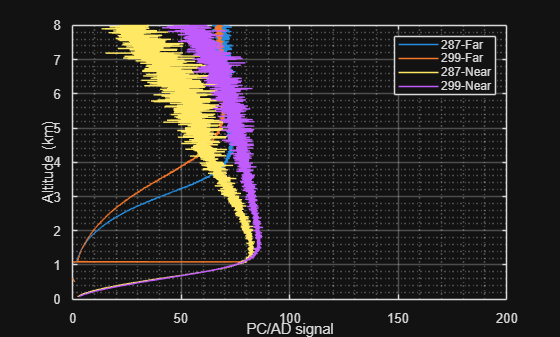

Show = true;
if Show == true
    id = 10;
    figure
    plot(gated_sigprof.pc287fr(:,id)./gated_sigprof.an287fr(:,id),hkm_fr); hold on
    plot(gated_sigprof.pc299fr(:,id)./gated_sigprof.an299fr(:,id),hkm_fr);
    plot(gated_sigprof.pc287nr(:,id)./gated_sigprof.an287nr(:,id),hkm_nr); hold on
    plot(gated_sigprof.pc299nr(:,id)./gated_sigprof.an299nr(:,id),hkm_nr);
    xlim([0,200]);legend('287-Far','299-Far','287-Near','299-Near')
    ylim([0,8]);grid on; grid minor;
    xlabel('PC/AD signal');
    ylabel('Altitude (km)');
end

## Glue the analog and photon counting signals where there are no clouds

[gated_sigprof.merge287fr, ~] = adpc_glue_func_cldscr(gated_sigprof.an287fr,gated_sigprof.pc287fr,5.5,6.5,hkm_fr,cldNum,cldBaseZ, cldTopZ);
[gated_sigprof.merge299fr, ~] = adpc_glue_func_cldscr(gated_sigprof.an299fr,gated_sigprof.pc299fr,5.5,6.5,hkm_fr,cldNum,cldBaseZ, cldTopZ);
[gated_sigprof.merge287nr, ~] = adpc_glue_func_cldscr(gated_sigprof.an287nr,gated_sigprof.pc287nr,1,1.1,hkm_nr,cldNum,cldBaseZ, cldTopZ);
[gated_sigprof.merge299nr, ~] = adpc_glue_func_cldscr(gated_sigprof.an299nr,gated_sigprof.pc299nr,1,1.1,hkm_nr,cldNum,cldBaseZ, cldTopZ);
[gated_sigprof.merge287frsib, ~] = adpc_glue_func_cldscr(gated_sigprof.an287frsib,gated_sigprof.pc287frsib,5.5,6.5,hkm_fr,cldNum,cldBaseZ, cldTopZ);

#### Merge the far and near range signal

% Merge range
start_merge_hkm = 0.9;
end_merge_hkm = 1;

% linear fitting coefficient calculating range
z1 = 0.9;
z2 = 1;
gated_sigprof.merge287merge = merge_nr_fr_prof(gated_sigprof.merge287nr,gated_sigprof.merge287frsib,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);
gated_sigprof.merge299merge = merge_nr_fr_prof(gated_sigprof.merge299nr,gated_sigprof.merge299fr,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);
gated_sigprof.merge287mergesib = merge_nr_fr_prof(gated_sigprof.an287nr,gated_sigprof.merge287frsib,start_merge_hkm,end_merge_hkm,hkm_fr,hkm_nr,z1,z2);

#### Cloud screened smoothed profiles

Show = false;
if Show == true
    id =1;

    y_lim = [0,10];
    tit_str='CCNY O3-DIAL AD Signal ';
    xlb='AD Signal (mV)';
    le={'287nm merge Far','299nm merge Far','287nm merge Near','299nm merge Near'};
    plot_fr_nr_Prof(gated_sigprof.an287frsib,gated_sigprof.an299fr,gated_sigprof.an287nr,gated_sigprof.an299nr,hkm_fr,hkm_nr,DateTime_avg,id,tit_str,xlb,y_lim,le);

    y_lim = [0,10];
    tit_str='CCNY O3-DIAL PC Signal ';
    xlb='PC Signal (MHz)';
    le={'287nm merge Far','299nm merge Far','287nm merge Near','299nm merge Near'};
    plot_fr_nr_Prof(gated_sigprof.pc287fr,gated_sigprof.pc299fr,gated_sigprof.pc287nr,gated_sigprof.pc299nr,hkm_fr,hkm_nr,DateTime_avg,id,tit_str,xlb,y_lim,le);

    xlb ='Merged Signal (MHz)';
    le = {'287nm merge Far','299nm merge Far','287nm Far-Near merged','299nm  Far-Near merged'};
    plot_fr_nr_Prof(gated_sigprof.merge287fr,gated_sigprof.merge299fr,gated_sigprof.merge287merge,gated_sigprof.merge299merge,hkm_fr,hkm_nr,DateTime_avg,id,tit_str,xlb,y_lim,le);
    title_str = strjoin(['Merged AD-PC signal',string(DateTime(1),'yyyyMMdd'),' ', string(DateTime((id-1)*nAvg+1),'HH:mm'),'-', string(DateTime(min([id*nAvg,length(TimeInHour)])),'HH:mm'),'UTC']);
    title(title_str)
end

## Calculate air density

- Option 1: using International Standard Atmosphere (ISA)

- Option 2: Micro-radiometer data (10-min resolution/daily average)

- Option 3: Radiosonde 

air_density_option = 3;
sigmaOn = 203.4*10^(-20); % O3 cross section at 287.2 (cm^2/molecule)
sigmaOff = 45.51*10^(-20); % O3 cross section at 299.1 (cm^2/molecule)
d_sigma = (sigmaOn-sigmaOff)*(10^-2)^2; % delta cross section (m^2/molecule)
load('./auxiliary_data/dsigma_287d1_299d2_temperature_lookup.mat');

% Option 1: Standard T and P profile,

TODO: option 1 is not producing something needed later in processing

if air_density_option == 1
    p0 = 1013.25*1e2; % surface pressure 1013.25 hpa = 101325pa
    T0 = 288.15; % surface temp (K)

    [NDAir_m3_prof, D_molex_prof, am287, am299] = isa_NDair_m3(hkm_nr,p0,T0,d_sigma);
    len_t = length(TimeInHour_avg);
    NDAir_m3 = repmat(NDAir_m3_prof, 1,len_t);
    D_molex = repmat(D_molex_prof, 1,len_t);

% Option 2: Micro-radiometer
elseif air_density_option == 2

% Option 3: Radiosonde data
elseif air_density_option == 3
    sondefile = './auxiliary_data/20241031_OKX_z12.txt';
    delimiter = 'tab';

    [NDAir_m3_prof, D_molex_prof, am287, am299, dsigma_hkm, P_prof, T_prof] = sonde_NDair_m3_dsigma_t(sondefile,hkm,dsigma,dsigma_temp,delimiter);
    len_t = length(TimeInHour_avg);
    NDAir_m3 = repmat(NDAir_m3_prof, 1,len_t);
    D_molex = repmat(D_molex_prof, 1,len_t);
end

## Calculating the ozone number density from the p_on and p_off

h0_nr = 0.2; h1_nr = 1.2;
len0_nr = 11; len1_nr = 121;
[frame_len_nr, vres_eff_nr] = framelen_vrtRes(hkm, h0_nr, h1_nr, len0_nr, len1_nr, dzm);

h0_fr = 1.2; h1_fr = 10;
len0_fr = 11; len1_fr = 551;
[frame_len_fr, vres_eff_fr] = framelen_vrtRes(hkm, h0_fr, h1_fr, len0_fr, len1_fr, dzm);

#### Effective Vertical Resolution Plot

Show = false;
if Show == true
    figure
    plot(vres_eff_nr, hkm, vres_eff_fr, hkm);
    xlabel('Effective Vertical Resolution (km)');
    ylabel('Altitude (km)');
    ylim([0,12]);
    grid on; legend('NR','FR')
    set(gca,'FontSize',15);
end

% Analog-PC FR - O3 Calculated from Analog-PC Merged Far Range Signals
N_O3_anpcmrg_fr = retrieve_o3ND_framelen(gated_sigprof.merge287frsib, gated_sigprof.merge299fr, dsigma_hkm(fr_id,:), frame_len_fr(fr_id));
N_O3_anpcmrg_fr = N_O3_anpcmrg_fr - D_molex(fr_id,:);

% Analog-PC NR - O3 Calculated from Analog-PC Merged Near Range Signals
N_O3_anpcmrg_nr = retrieve_o3ND_framelen(gated_sigprof.merge287nr, gated_sigprof.merge299nr, dsigma_hkm(nr_id,:), frame_len_fr(nr_id));
N_O3_anpcmrg_nr = N_O3_anpcmrg_nr - D_molex(nr_id,:);

% Analog FR - O3 Calculated from Far Range Analog Channels Only
N_O3_an_fr = retrieve_o3ND_framelen(gated_sigprof.an287frsib, gated_sigprof.an299fr, dsigma_hkm(fr_id,:), frame_len_fr(fr_id));
N_O3_an_fr = N_O3_an_fr - D_molex(fr_id,:);

% Analog NR - O3 Calculated from Near Range Analog Channels Only
N_O3_an_nr = retrieve_o3ND_framelen(gated_sigprof.an287nr, gated_sigprof.an299nr, dsigma_hkm(nr_id,:), frame_len_nr(nr_id));
N_O3_an_nr = N_O3_an_nr - D_molex(nr_id,:);

% Photon Counting FR - O3 Calculated from Far Range Photon Counting Channels Only
N_O3_pc_fr = retrieve_o3ND_framelen(gated_sigprof.pc287frsib, gated_sigprof.pc299fr, dsigma_hkm(fr_id,:), frame_len_fr(fr_id));
N_O3_pc_fr = N_O3_pc_fr - D_molex(fr_id,:);

% Photon Counting NR - O3 Calculated from Near Range Photon Counting Channels Only
N_O3_pc_nr = retrieve_o3ND_framelen(gated_sigprof.pc287nr, gated_sigprof.pc299nr, dsigma_hkm(nr_id,:), frame_len_nr(nr_id));
N_O3_pc_nr = N_O3_pc_nr - D_molex(nr_id,:);

Merge Near and Far Range O3 Profiles

start_merge_hkm = 0.83;
end_merge_hkm = 0.9;

% Analog-PC Merge FR, Analog NR
N_O3_merge = merge_nr_fr_o3ND(N_O3_an_nr, N_O3_anpcmrg_fr, start_merge_hkm, end_merge_hkm, hkm_fr, hkm_nr);

% Analog-PC Merge FR-NR Merge
N_O3_anpcmrg_merge = merge_nr_fr_o3ND(N_O3_anpcmrg_nr, N_O3_anpcmrg_fr, start_merge_hkm, end_merge_hkm, hkm_fr, hkm_nr);

% Analog FR-NR Merge
N_O3_an_merge = merge_nr_fr_o3ND(N_O3_an_nr, N_O3_an_fr, start_merge_hkm, end_merge_hkm, hkm_fr, hkm_nr);

% Photon Counting FR-NR Ozone Merge
N_O3_pc_merge = merge_nr_fr_o3ND(N_O3_pc_nr, N_O3_pc_fr, start_merge_hkm, end_merge_hkm, hkm_fr, hkm_nr);

## Calculate the SNR

bg299_fr = repmat(sigprof.bgpc299,length(hkm_fr),1);
bg287_fr = repmat(sigprof.bgpc287,length(hkm_fr),1);
snr_299_fr = sqrt(nAvg*1200/40*(gated_sigprof.merge299fr).^2./(gated_sigprof.merge299fr+bg299_fr));
snr_287_fr = sqrt(nAvg*1200/40*(gated_sigprof.merge287fr).^2./(gated_sigprof.merge287fr+bg287_fr));

bg299_nr = repmat(sigprof.bgpc299nr,length(hkm_nr),1);
bg287_nr = repmat(sigprof.bgpc287nr,length(hkm_nr),1);
snr_299_nr = sqrt(nAvg*1200/40*(gated_sigprof.merge299nr).^2./(gated_sigprof.merge299nr+bg299_nr));
snr_287_nr = sqrt(nAvg*1200/40*(gated_sigprof.merge287nr).^2./(gated_sigprof.merge287nr+bg287_nr));

#### SNR Plot

Show = false;
if Show == true
    id = 1;
    figure
    plot(snr_287_fr(:,id),hkm_fr,'g');hold on
    plot(snr_299_fr(:,id),hkm_fr,'k');
    plot(snr_287_nr(:,id),hkm_nr,'b');
    plot(snr_299_nr(:,id),hkm_nr,'r');
    set(gca,'XScale','log')
    legend('287 nm-far','299 nm_far','287 nm-near','299 nm_near')
    xlabel('SNR');
    ylabel('Altitude (km)');
    title(['SNR ',string(DateTime_avg(id))])
    ylim([0,10])
    grid on
end

## Calculate the O3 ppb

O3ppb_mrg = N_O3_merge./NDAir_m3(nr_id,:)*1e9;

O3ppb_anpcmrg_fr = N_O3_anpcmrg_fr./NDAir_m3(fr_id,:)*1e9;
O3ppb_anpcmrg_nr = N_O3_anpcmrg_nr./NDAir_m3(nr_id,:)*1e9;

O3ppb_an_fr = N_O3_an_fr./NDAir_m3(fr_id,:)*1e9;
O3ppb_an_nr = N_O3_an_nr./NDAir_m3(nr_id,:)*1e9;

O3ppb_pc_fr = N_O3_pc_fr./NDAir_m3(fr_id,:)*1e9;
O3ppb_pc_nr = N_O3_pc_nr./NDAir_m3(nr_id,:)*1e9;

O3ppb_mrg_an = N_O3_an_merge./NDAir_m3(nr_id,:)*1e9;
O3ppb_mrg_pc = N_O3_pc_merge./NDAir_m3(nr_id,:)*1e9;

Saves the different O3 mixing ratio profiles and altitude data for plotting later

save(fullfile(save_path,strcat('O3lidar_results_',file_date,'.mat')), "O3ppb*", "hkm", "hkm_nr", "hkm_fr");

#### O3 Profile Plot

Show = false;
if Show == true
    id = 1;
    figure
    hold on;
    plot(O3ppb_an_nr(:,id), hkm_nr,'b-','LineWidth',1.5);
    plot(O3ppb_anpcmrg_fr(:,id), hkm_fr,'r-','LineWidth',1.5);
    plot(O3ppb_mrg(:,id), hkm_nr,'k-','LineWidth',1.5);    
    legend('Near Range','Far Range','Merge')
    xlabel('Ozone Mixing Ratio (ppb)');
    ylabel('Altitude (km)');
    title(strjoin([string(DateTime_avg(1),'yyyyMMdd '), string(DateTime((id-1)*nAvg+1),'HH:mm'),'-', string(DateTime(min([id*nAvg,length(TimeInHour)])),'HH:mm'),'UTC']))
    ylim([0.2,12]);xlim([0 200]);
    grid on; grid minor 
    set(gca,'FontSize',16)
end
Show = false;
if Show == true
    id = 1;
    figure
    hold on;
    plot(O3ppb_an_nr(:,id),hkm_nr);
    plot(O3ppb_an_fr(:,id),hkm_fr);
    plot(O3ppb_pc_nr(:,id),hkm_nr);
    plot(O3ppb_pc_fr(:,id),hkm_fr);

    legend('An NR','An FR','PC NR','PC FR')
    xlabel('Ozone Mixing Ratio (ppb)');
    ylabel('Altitude (km)');
    title(strjoin([string(DateTime_avg(1),'yyyyMMdd '), string(DateTime((id-1)*nAvg+1),'HH:mm'),'-', string(DateTime(min([id*nAvg,length(TimeInHour)])),'HH:mm'),'UTC']))
    ylim([0.2,12]);xlim([0 200]);
    grid on; grid minor 
    set(gca,'FontSize',16)
end
Show = false;
if Show == true
    id = 1;
    figure
    hold on;
    plot(O3ppb_mrg_an(:,id),hkm_nr);
    plot(O3ppb_mrg_pc(:,id),hkm_nr);

    legend('An FR-NR','PC FR-NR')
    xlabel('Ozone Mixing Ratio (ppb)');
    ylabel('Altitude (km)');
    title(strjoin([string(DateTime_avg(1),'yyyyMMdd '), string(DateTime((id-1)*nAvg+1),'HH:mm'),'-', string(DateTime(min([id*nAvg,length(TimeInHour)])),'HH:mm'),'UTC']))
    ylim([0.2,12]);xlim([0 200]);
    grid on; grid minor 
    set(gca,'FontSize',16)
end

movnum1 = 21; % 200m 0-2km 1:533
O3ppb_cld = O3ppb_mrg;
N_O3_cld = N_O3_merge;
O3ppb_cld(cld_mask) = nan;
N_O3_cld(cld_mask) = nan;

N_O3_sm = movmean(N_O3_cld,movnum1,1);
O3ppb_sm = movmean(O3ppb_cld,movnum1,1);

snr_287_fr_sm = movmean(snr_287_fr,10,1);

snrmask_fr = snr_287_fr_sm < 10;
snrmask_fr_nr = logical([zeros(diff_nr_fr,size(snr_287_fr_sm,2)); snrmask_fr]);

cld_mask_fr = cld_mask(diff_nr_fr+1:end,:);

## Calculate the aerosol correction term

Sm = 8*pi/3;
Sa = 50;   % 60 for smoke; 50 for urban aerosols
Rc = 1.005;  % reference value for the total-backscatter to molecular backscatter ratio
zsurf = 0.3;
zref = 8.0;   % 6.5, 7.5, 8.0 8.5

prof_299 = movmean(gated_sigprof.merge299merge,3,1);
sigmaOff = 45.51*10^(-20);% O3 cross section at 299.1 (cm^2/molecule)
ae = 1.5;

N_O3 = movmean(N_O3_merge,21,1);
[~, abs299, aext299, N_absc_299, D_aext_299, rel_NO3] = o3_aerosol_iterative_solver(prof_299,hkm_nr,N_O3,Sm,Sa,Rc,zsurf,zref,am299(nr_id),sigmaOff,ae,dsigma_hkm(nr_id),frame_len_nr,dzm);   

img_id = (imag(abs299)~=0);
abs299(img_id) = nan;
abs299(:,cldBaseZ(1,:) < 6) = nan; % if there is cloud lower than 6km, remove the aerosol retrieval
abs299(hkm_nr<0.6,:) = nan;aext299(hkm_nr < 0.6,:) = nan;
N_absc_299(hkm_nr < 0.6,:) = nan;D_aext_299(hkm_nr < 0.6,:) = nan;
N_absc_299(:,cldBaseZ(1,:) < 6) = nan;D_aext_299(:,cldBaseZ(1,:) < 6) = nan;
N_O3_corr = N_O3_merge - fillmissing(N_absc_299,'constant',0) - fillmissing(D_aext_299,'constant',0);

#### Aerosol Backscatter Coefficient Plot

Show = false;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' aerosol backscatter coefficient (/km/sr) at 299-nm, NYC'];
    NDplot(abs299,TimeInHour_avg,hkm_nr,title_str,[0.5,zref],[0,3e-3],14);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');
end

#### Aerosol Correction Plot

Show = false;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL aerosol correction term'];
    NDplot2(N_absc_299./NDAir_m3(nr_id,:)*1e9,TimeInHour_avg,hkm_nr,title_str,[0.6,zref],[-15,15],14);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');
end

Systematic error due to S ratio and AE

ae1 = 1;
[N_O3_corr1,abs299_1,~,N_absc_299_1,D_aext_299_1,rel_NO3_1] = o3_aerosol_iterative_solver(prof_299,hkm_nr,N_O3_sm,Sm,Sa,Rc,zsurf,zref,am299(nr_id),sigmaOff,ae1,dsigma_hkm(nr_id),frame_len_nr,dzm);   

eps_sys_aero = (N_absc_299_1-N_absc_299) ./ N_O3_corr;

Interference gas correction

sigma_so2_off = 4.073526E-19; % unit: cm2/molec
sigma_so2_on = 9.360870E-19;
dsigma_so2 = (sigma_so2_on - sigma_so2_off)*(10^-2)^2; %m2/molec

sigma_no2_off = 1.286967E-19; % unit: cm2/molec
sigma_no2_on = 7.455643E-20;
dsigma_no2 = (sigma_no2_on-sigma_no2_off)*(10^-2)^2; %m2/molec

## Calculate the statistical uncertainty

s_nr = 1./(snr_299_nr.^2) + 1./(snr_287_nr.^2) ;
s_fr = 1./(snr_299_fr.^2) + 1./(snr_287_fr.^2) ;
eps_nr = nan(size(s_nr)); 
eps_fr = nan(size(s_fr));

for k = 1:len_t
    eps_nr(:,k) = sqrt(s_nr(:,k))./(2*dsigma_hkm(nr_id).*N_O3_merge(:,k).*(vres_eff_nr(nr_id)*1e3));
    eps_fr(:,k) = sqrt(s_fr(:,k))./(2*dsigma_hkm(fr_id).*N_O3_merge(diff_nr_fr+1:end,k).*(vres_eff_fr(fr_id)*1e3));
end

k1 = find(hkm_nr >= start_merge_hkm,1,'first');
k2 = find(hkm_fr >= start_merge_hkm,1,'first');
eps_sta_mrg = eps_nr;
eps_sta_mrg(k1:end,:) = eps_fr(k2:end,:);
eps_sta_mrg(imag(eps_sta_mrg) ~=0) = 1;

Estimate the systematic uncertainty and combined uncertainty 

eps_sys_NO2 = 0.005 ;
eps_sys_SO2 = 0.01 ;
eps_sys_Rayleigh = 0.01;
eps_sys_dsigma = 0.03;

eps_sys = sqrt(eps_sys_NO2.^2 + eps_sys_SO2.^2 + eps_sys_Rayleigh.^2 + eps_sys_dsigma.^2 + eps_sys_aero.^2);
eps_combined = sqrt(eps_sta_mrg.^2 + fillmissing(eps_sys,'constant',0).^2);

Smoothing and screening

movnum1 = 51; % 200m 0-2km 1:533
% N_O3_cld = N_O3_corr;
% N_O3_cld(cld_mask) = nan;
% N_O3_corr_scr = movmean(N_O3_cld,movnum1,1);

uncrmask = eps_sta_mrg>0.5|isnan(eps_sta_mrg)|eps_sta_mrg<0;

% O3ppb_corr = N_O3_corr./NDAir_m3(nr_id,:)*1e9;

### Ozone Time-Height Plot

The plot can use data processed from different channels

#### Main: 

    FR Analog and Photon Counting signals are glued and processed

    NR Analog signals processed 

    Resulting FR and NR O3 profiles are merged

#### Analog-PC Merge Far-Range:

    O3 processed from only FR Analog and Photon Counting signals glued together

#### Analog Far-Range:

    O3 processed from only FR Analog signals

#### Analog Near-Range

    O3 processed from only NR Analog signals

#### Photon-Counting Far-Range:

    O3 processed from only FR Photon-Counting signals

#### Photon-Counting Near-Range

    O3 processed from only NR Photon-Counting signals

zmin_o3 = 0.5;
zmax_o3 = 8;

sets = ["Main" "Analog-PC Merge Far-Range" "Analog Far-Range" "Analog Near-Range" "Photon-Counting Far-Range" "Photon-Counting Near-Range"];
dataset_to_plot = sets(1);
if dataset_to_plot == sets(1)
    data = N_O3_merge;
    y = hkm_nr;

elseif dataset_to_plot == sets(2)
    data = N_O3_anpcmrg_fr;
    y = hkm_fr;

elseif dataset_to_plot == sets(3)
    data = N_O3_an_fr;
    y = hkm_fr;

elseif dataset_to_plot == sets(4)
    data = N_O3_an_nr;
    y = hkm_nr;

elseif dataset_to_plot == sets(5)
    data = N_O3_pc_fr;
    y = hkm_fr;

elseif dataset_to_plot == sets(6)
    data = N_O3_pc_nr;
    y = hkm_nr;

end

aerosol_correction = true;
if aerosol_correction == true
    if size(data,1) == size(hkm_nr,1)
        data = data - fillmissing(N_absc_299,'constant',0) - fillmissing(D_aext_299,'constant',0);
    else
        data = data - fillmissing(N_absc_299(diff_nr_fr+1:end,:),'constant',0) - fillmissing(D_aext_299(diff_nr_fr+1:end,:),'constant',0);
    end
end

clear_clouds = true;
if clear_clouds == true
    if size(data,1) == size(hkm_nr,1)
        data(cld_mask) = NaN;

    elseif size(data,1) == size(hkm_fr,1)
        data(cld_mask_fr) = NaN;
    end
end

smooth_profile = true;
if smooth_profile == true
    data = movmean(data,movnum1,1);
end

for old data, Clearing low SNR data might not work at the moment

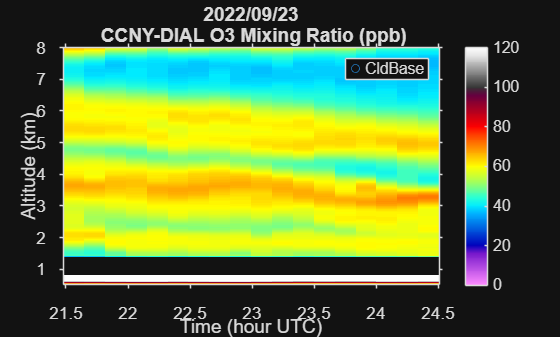

clear_low_snr = true;
if clear_low_snr == true
    if size(data,1) == size(hkm_nr,1)
        data(snrmask_fr_nr) = NaN;

    elseif size(data,1) == size(hkm_fr,1)
        data(snrmask_fr) = NaN;
    end

    if size(data,1) == size(hkm_nr,1)
        data(uncrmask) = NaN;
    else
        data(uncrmask(diff_nr_fr+1:end,:)) = NaN;
    end
end

if size(data,1) == size(hkm_nr,1)
    data = data./NDAir_m3(nr_id,:)*1e9;
else
    data = data./NDAir_m3(fr_id,:)*1e9;
end

data(data<=0) = NaN;

Show = true;
if Show == true
    title_str = [string(DateTime_avg(1),'yyyy/MM/dd'),' CCNY-DIAL O3 Mixing Ratio (ppb)'];
    NDplot2(data,TimeInHour_avg,y,title_str,[zmin_o3,zmax_o3],[0,120],13);
    hold on; plot(linspace(TimeInHour_avg(1),TimeInHour_avg(end),length(TimeInHour_avg)),cldBaseZ(1,:),'o'); legend('CldBase');
end